%Verdonk HW7 Q1

%Let dx=xCF-xNew, and dx=?ln(alpha)

%Given in problem:
L=0.191;
a=0.1:1:10;

%Part A:
%First let's load an image
image=imread('BicoidCephalicFurrowdata/1.0x/Bcd2XAEm01CF_whole.tif');
imshow(image, [0, 10]);
%The two numbers inside the square brackets set the min and max pixel 
%values. So anything below the min is set to the min and anything above the
%max is set to the max pixel intensity

%How will we measure the length of the embryo? Use this tool! Once the new
%window pops up, click once on the anterior tip of the embryo (with the 
%highest Bicoid concentration) and then once on the posterior tip. Then 
%click enter. The two points will be stored as coordinates in a matrix 
%called AP.
AP=ginput; %AP = Anterior Posterior

%Let's define two vectors for our clicks. The first will be our x-values.
APx=[AP(1,1), AP(2,1)];
%The second vector will be for our y-values.
APy=[AP(1,2),AP(2,2)];

%Let's input where the cephalic furrow is using ginput
CF=ginput(2);
%again creating vectors for our coordinatess
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];


%Step 1: Find the equations for both lines above. y-y1=m(x-x1)
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));


%Step 2: Find where the lines intercept
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;


%Step 3: Find the lengths of both lines. The "length" of the cephalic
%furrow is defined as the distance from the anterior tip to the
%intersection point between the two lines.
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));


%Step 4: Find xCF
xCF01=LCF/LAP;


%Step 5: Repeat for the other two images
%Image 2
image=imread('BicoidCephalicFurrowdata/1.0x/Bcd2XAEm16CF_whole.tif');
imshow(image, [0, 10]);
AP2=ginput; %AP = Anterior Posterior
APx2=[AP2(1,1), AP2(2,1)];
APy2=[AP2(1,2),AP2(2,2)];
CF2=ginput(2); %CF = Cephalic Furrow
CFx2=[CF2(1,1), CF2(2,1)]; 
CFy2=[CF2(1,2), CF2(2,2)];
mAP2=(APy2(2)-APy2(1))/(APx2(2)-APx2(1));
bAP2=APy2(1)-(mAP2*APx2(1));
mCF2=(CFy2(2)-CFy2(1))/(CFx2(2)-CFx2(1));
bCF2=CFy2(1)-(mCF2*CFx2(1));
xI2=(bCF2-bAP2)/(mAP2-mCF2);
yI2=(mAP2*xI2)+bAP2;
LAP2=sqrt(((APx2(2)-APx2(1))^2)+((APy2(2)-APy2(1))^2));
LCF2=sqrt(((xI2-APx2(1))^2)+((yI2-APy2(1))^2));
xCF16=LCF2/LAP2;

%Image 3
image=imread('BicoidCephalicFurrowdata/1.0x/Bcd2XAEm29CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF29=LCF/LAP;



%Finally, plot average xCF on a linear-log plot, with x=log([BCD dosage]) and
%y=cephalic furrow position in embryo. (apparently the linlog plot is
%really more important for part b than for this part)

xCF_avg=(xCF01+xCF16+xCF29)/3;
xnew=L*log(a)+xCF_avg
semilogx(a, xnew)
hold on
scatter(1.0, xCF_avg)
xlabel("log(Bicoid Dosage)")
ylabel("New Cephalic Furrow Position")
hold off





%Part B
%Repeat the steps above, this time with three embryos from 0.52x, 1.57x,
%and 2.34x, respectively

%0.52x
%Image 1
image=imread('BicoidCephalicFurrowdata/0.52x/BCD1Em14CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF052_14=LCF/LAP;

%Image 2
image=imread('BicoidCephalicFurrowdata/0.52x/BCD1Em22CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF052_22=LCF/LAP;

%Image 3
image=imread('BicoidCephalicFurrowdata/0.52x/BCD1Em27CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF052_27=LCF/LAP;

%1.57x
%Image 1
image=imread('BicoidCephalicFurrowdata/1.57x/BCD4Em22CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF157_22=LCF/LAP;

%Image 2
image=imread('BicoidCephalicFurrowdata/1.57x/BCD4Em28CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF157_28=LCF/LAP;

%Image 3
image=imread('BicoidCephalicFurrowdata/1.57x/BCD4Em39CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF157_39=LCF/LAP;


%2.34x
%Image 1
image=imread('BicoidCephalicFurrowdata/2.34x/BCD56Em02CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF234_02=LCF/LAP;

%Image 2
image=imread('BicoidCephalicFurrowdata/2.34x/BCD56Em10CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF234_10=LCF/LAP;

%Image 3
image=imread('BicoidCephalicFurrowdata/2.34x/BCD56Em18CF_whole.tif');
imshow(image, [0, 10]);
AP=ginput;
APx=[AP(1,1), AP(2,1)];
APy=[AP(1,2),AP(2,2)];
CF=ginput(2);
CFx=[CF(1,1), CF(2,1)]; 
CFy=[CF(1,2), CF(2,2)];
mAP=(APy(2)-APy(1))/(APx(2)-APx(1));
bAP=APy(1)-(mAP*APx(1));
mCF=(CFy(2)-CFy(1))/(CFx(2)-CFx(1));
bCF=CFy(1)-(mCF*CFx(1));
xI=(bCF-bAP)/(mAP-mCF);
yI=(mAP*xI)+bAP;
LAP=sqrt(((APx(2)-APx(1))^2)+((APy(2)-APy(1))^2));
LCF=sqrt(((xI-APx(1))^2)+((yI-APy(1))^2));
xCF234_18=LCF/LAP;

Now, for the graphing step

%Finally, plot each xCF on the same linear-log plot as in Part A
xCF052=(xCF052_14+xCF052_22+xCF052_27)/3;
xCF157=(xCF157_22+xCF157_28+xCF157_39)/3;
xCF234=(xCF234_02+xCF234_10+xCF234_18)/3;
xnew=L*log(a)+xCF_avg;

xnew =    -0.0848    0.3732    0.4967    0.5711    0.6245    0.6662    0.7004    0.7294    0.7545    0.7768


semilogx(a, xnew)
hold on
scatter(0.52, xCF052)
scatter(1.0, xCF_avg)
scatter(1.57, xCF157)
scatter(2.34, xCF234)
xlabel("log(Bicoid Dosage)")
ylabel("New Cephalic Furrow Position")
lgd = legend('Cephalic Furrow Position Prediction', 'a=0.52x', 'a=1.0x', 'a=1.57x', 'a=2.34x');

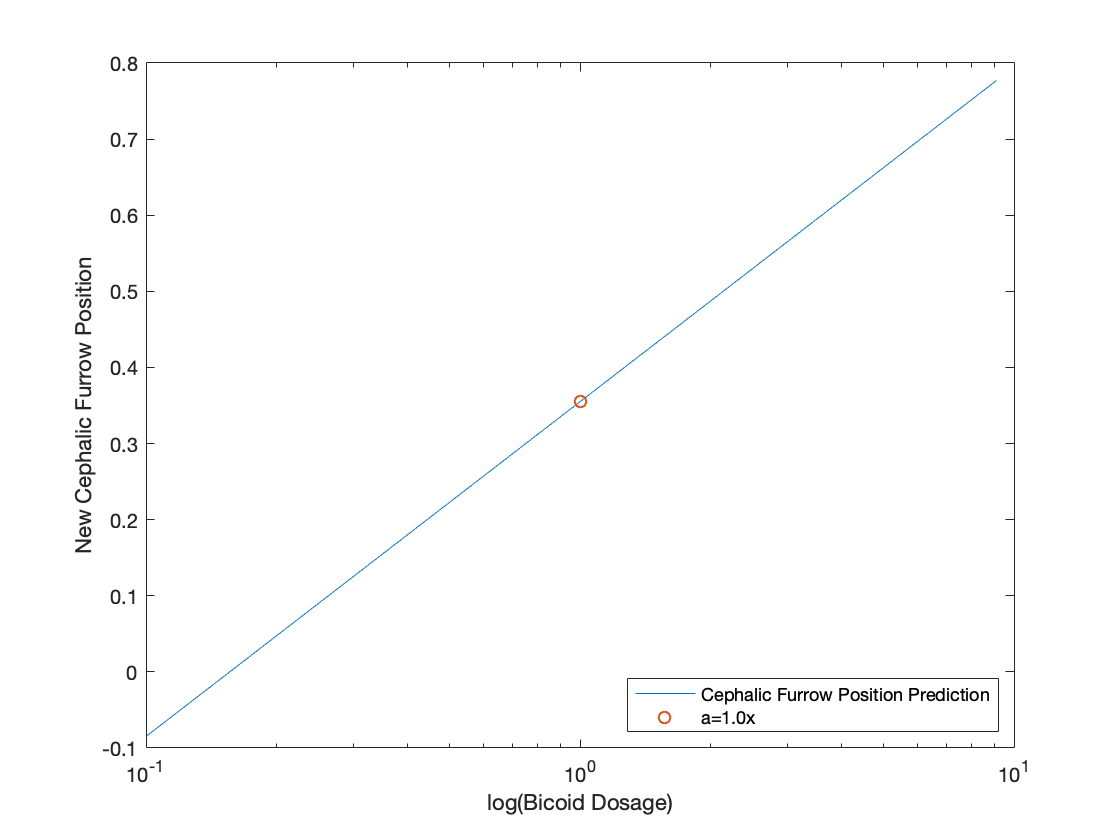

lgd.Location = 'southeast';
hold off